# Lab 2: PCA-based Face Recognition

Submission : Blackboard, by 1:30PM on Wednesday, 18 September, 2019

## Dataset

We will use the ORL database, available to download on AT&T’s web site. This database contains photographs showing the faces of 40 people. Each one of them was photographed 10 times. These photos are stored as grayscale images with $112\times92$ pixels. 

In our example, we construct a catalog called `orlfaces`, comprised of people named $s_1, s_2, . . . , s_{40}$, each one of them containing 10 photographs of the person. The data has already been split into a training and testing split, where for each person, we use the first 9 photographs for training and the last photograph for test.

1. Load the training data

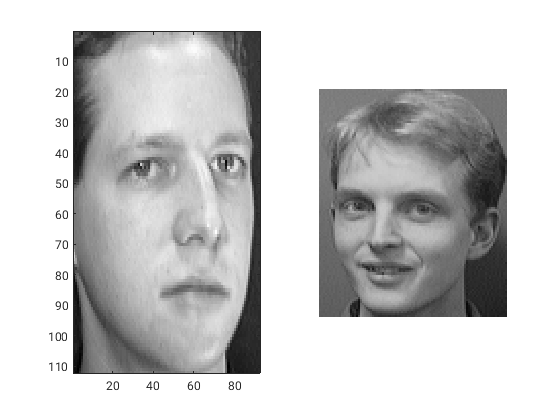

% Your code goes here
% Mo Zhou <mzhou32@jhu.edu>
facesTrain = zeros(112*92, 40*9);
for i = 1:40
    for j = 1:9
        filename = sprintf("orl_faces/Train/s%d/%d.pgm", i, j);
        tmp = imread(filename);
        tmp = reshape(tmp, 112*92, 1);
        facesTrain(:, (i-1)*9+j) = double(tmp);
        %[i, j]
    end
end
facesTest = zeros(112*92, 40);
for i = 1:40
    filename = sprintf("orl_faces/Test/s%d/10.pgm", i);
    tmp = imread(filename);
    tmp = reshape(tmp, 112*92, 1);
    facesTest(:, i) = double(tmp);
    %[i]
end
facesTrain = double(facesTrain);
facesTest = double(facesTest);

% show example
imshow(uint8(reshape(facesTrain(:,360), 112, 92)));
imshow(uint8(reshape(facesTest(:,40), 112, 92)));

 2. Change each $(d_1, d_2) = (112, 92)$ photograph into a vector

% Your code goes here
disp("flattening into vector is already done during data loading");

flattening into vector is already done during data loading


3. Using all the training photographs for the $N$ people in the training dataset, construct a subspace $H$with dimensionality less than or equal to $N$such that this subspace has the maximum dispersion for the $N$ projections. To extract this subspace, use Principal Component Analysis, as described below - 

- Center the data

- Compute the correlation matrix

- Use either the `SVD` or `eig` functions to perform SVD and get the eigenvectors and eigenvalues for the correlation matrix.

- Normalize the eigenvectors by the corresponding eigenvalues.

% Your code goes here

% 1. center the data
meanTrain = mean(facesTrain, 2);
xTrain = facesTrain - meanTrain;

% 2. compute the correlation matrix
xtx = xTrain.' * xTrain;

% 3. compute eig of the correlation matrix
[U, D] = eig(xtx);
assert(norm(xtx * U - U * D) < 1e-3);
V = xTrain * U';

% 4. normalize
%VV = V + meanTrain;
VV = V;
VV = (VV - min(VV))./(max(VV)-min(VV));
eigval = diag(D);
eigval = eigval(end:-1:1);
VV = fliplr(VV);
V = fliplr(V);

4. Plot the eigenvalues

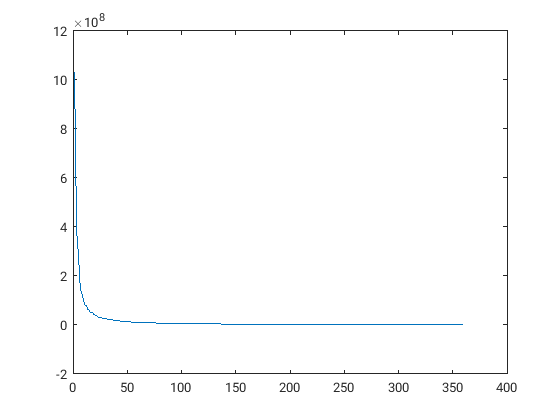

% Your code goes here
figure;
plot(eigval);

5. Plot the first 3 eigenfaces and the last eigenface (these will be the correctly reshaped eigenvectors)

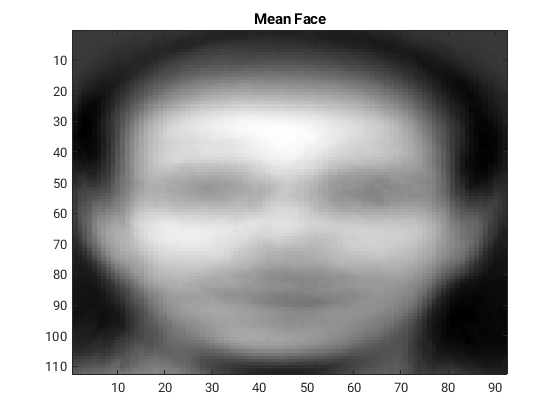

% Your code goes here

% let first look at the mean face
figure, imagesc(reshape(meanTrain, 112, 92));
colormap gray; title("Mean Face");

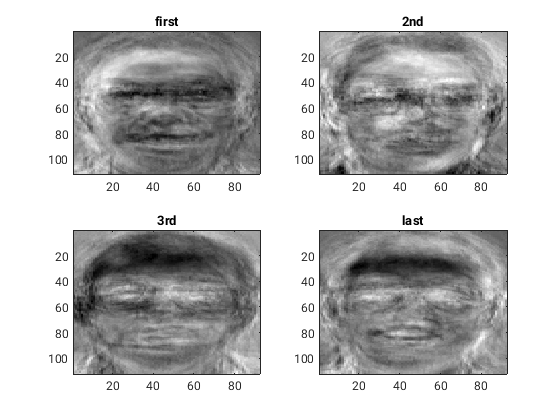

% then the eigenfaces
figure; subplot(2,2,1);
imagesc(reshape(VV(:,1), 112, 92));
colormap gray; title("first");
subplot(2,2,2);
imagesc(reshape(VV(:,2), 112, 92));
colormap gray; title('2nd');
subplot(2,2,3);
imagesc(reshape(VV(:,3), 112, 92));
colormap gray; title('3rd');
subplot(2,2,4);
imagesc(reshape(VV(:,end), 112, 92));
colormap gray; title('last');

6. Pick a face and reconstruct it using $k = {10, 20, 30, 40}$ eigenvectors. Plot all of these reconstructions and compare them. For each value of $k$, plot the original image, reconstructed image, and the difference b/w the original image and reconstruction in each case. Write your observations.

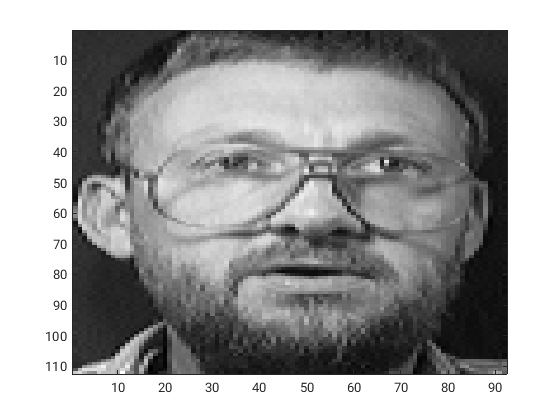

% Your code goes here
pickface = facesTrain(:,123);
pface = pickface - meanTrain;
figure; imagesc(reshape(pickface, 112, 92));
colormap gray;

x10 = lsqr(V(:,1:10), pface);

lsqr converged at iteration 10 to a solution with relative residual 0.75.


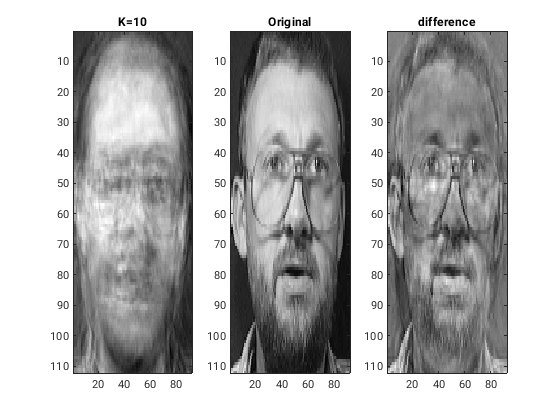

figure; subplot(1,3,1);
imagesc(reshape(V(:,1:10)*x10+meanTrain, 112, 92));
colormap gray; title("K=10");
subplot(1,3,2); imagesc(reshape(pickface, 112, 92));
colormap gray; title('Original');
subplot(1,3,3);
imagesc(reshape(pickface, 112, 92)- ...
    reshape(V(:,1:10)*x10+meanTrain, 112, 92));
title("difference")

x20 = lsqr(V(:,1:20), pface);

lsqr converged at iteration 15 to a solution with relative residual 0.71.


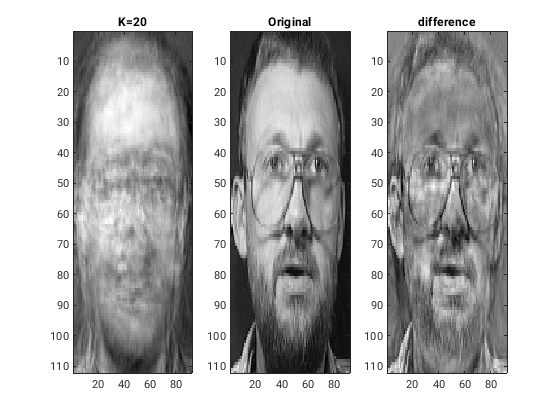

figure; subplot(1,3,1);
imagesc(reshape(V(:,1:20)*x20+meanTrain, 112, 92));
colormap gray; title("K=20");
subplot(1,3,2); imagesc(reshape(pickface, 112, 92));
colormap gray; title('Original');
subplot(1,3,3); imagesc(reshape(pickface, 112, 92) ...
    -reshape(V(:,1:20)*x20+meanTrain, 112, 92));
title("difference")

x30 = lsqr(V(:,1:30), pface);

lsqr converged at iteration 18 to a solution with relative residual 0.64.


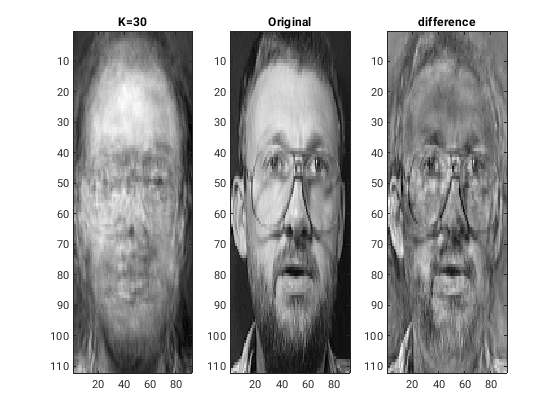

figure; subplot(1,3,1);
imagesc(reshape(V(:,1:30)*x30+meanTrain, 112, 92));
colormap gray; title("K=30");
subplot(1,3,2); imagesc(reshape(pickface, 112, 92));
colormap gray; title('Original');
subplot(1,3,3); imagesc(reshape(pickface, 112, 92)- ...
    reshape(V(:,1:30)*x30+meanTrain, 112, 92));
title("difference")

x40 = lsqr(V(:,1:40), pface);

lsqr stopped at iteration 20 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 0.59.


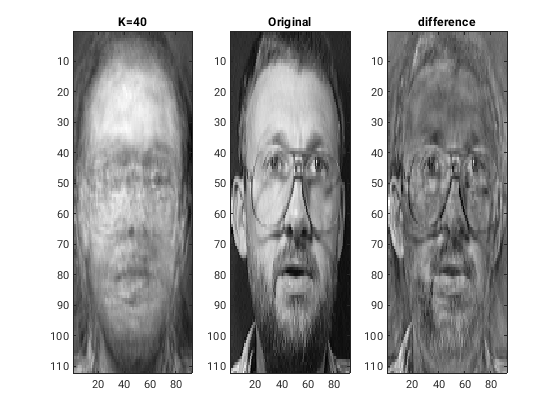

figure; subplot(1,3,1);
imagesc(reshape(V(:,1:40)*x40+meanTrain, 112, 92));
colormap gray; title("K=40");
subplot(1,3,2); imagesc(reshape(pickface, 112, 92));
colormap gray; title('Original');
subplot(1,3,3); imagesc(reshape(pickface, 112, 92)- ...
    reshape(V(:,1:40)*x40+meanTrain, 112, 92));
title("difference")

x200 = lsqr(V(:,1:200), pface);

lsqr stopped at iteration 20 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 0.29.


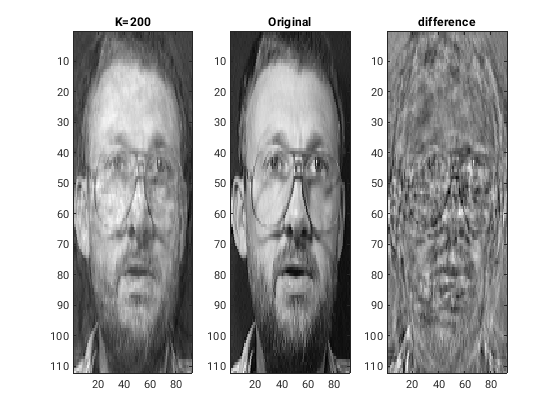

figure; subplot(1,3,1);
imagesc(reshape(V(:,1:200)*x200+meanTrain, 112, 92));
colormap gray; title("K=200");
subplot(1,3,2); imagesc(reshape(pickface, 112, 92));
colormap gray; title('Original');
subplot(1,3,3); imagesc(reshape(pickface, 112, 92)- ...
    reshape(V(:,1:200)*x200+meanTrain, 112, 92));
title("difference")

disp("with a larger K, the restored image will be more clear and detailed.");

with a larger K, the restored image will be more clear and detailed.


disp("For example, the glass for the above person is only restored with a very large K");

For example, the glass for the above person is only restored with a very large K


7. Load the testing data, and reshape it similar to the training data.

% Your code goes here
disp("it's already done in part 1")

it's already done in part 1


size(facesTest)

ans =        10304          40


8. For each photograph in the testing dataset, you will implement a classifier to predict the identity of the person. To do this, follow these steps - 

- Determine the projection of each test photo onto $H$ with different dimensionalities $d = {10, 20, 30, 40}$

- Compare the distance of this projection to the projections of all images in the training data.

- For each test photo's projection, find the closest category of projection in the training data.

% Your code goes here
ftest = facesTest - meanTrain;
for d = 10:10:40
    disp(sprintf("Case K=%d", d));
    w = pinv(V(:,1:d)) * ftest;
    ref = pinv(V(:,1:d)) * xTrain;
    cate = zeros(1,40);
    for i = 1:40
        wi = w(:,i);
        dist = vecnorm(ref - wi);
        [m, idx] = min(dist);
        cate(i) = ceil((idx-1)/9);
    end
    cate
    % let's calculate the accuracy
    accuracy = sum(cate == 1:40)/40;
    fprintf("accuracy is %f", accuracy);
end

Case K=10


cate =     13     2     3     4     5     6     7     8     9     4    10    12    13    14    15    16    17    18    18    19    21    22    22    24    25    26     2    28    29    30    31    32    33    34    40    36    37    38    39    40


accuracy is 0.800000

Case K=20


cate =      1     2     3     4     5     6     7     8     9     3    11    12    13    14    15    16    17    18    19    20    21    22    22    24    25    26    26    28    29    30    31    32    33    34    35    28    37    38    39    40


accuracy is 0.900000

Case K=30


cate =     16     2     3     4    18     6     7     8     9     3    10    12    13    14    15    16    17    18    18    19    21    22    22    24    25    26    26    28    28    29    31    32    33    34    35    36    37    38    39     4


accuracy is 0.725000

Case K=40


cate =     16     2     3     4    40     6     7     8     9     3    10    12    13    14    15    16    17    18    18    19    21    22    22    24    25    26    26    28    29    29    31    32    33    34    35    36    37    38    39     4


accuracy is 0.750000

9. Show the closest image in the training dataset for the $s_1$ test example.

% Your code goes here
dist = vecnorm(xTrain - ftest(:,1));
[m, idx] = min(dist);
disp(idx);

     5



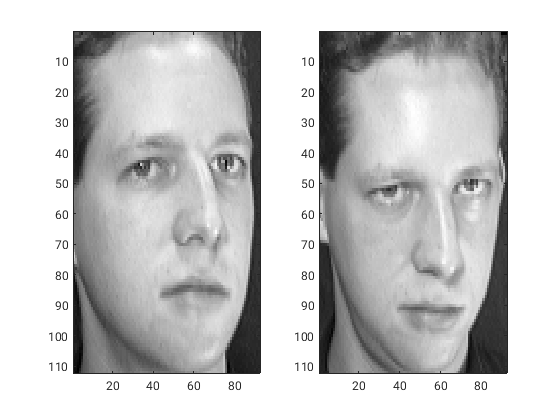

figure; subplot(1,2,1);
imagesc(reshape(xTrain(:,idx) + meanTrain, 112, 92));
colormap gray;
subplot(1,2,2);
imagesc(reshape(ftest(:,1) + meanTrain, 112, 92));
colormap gray;